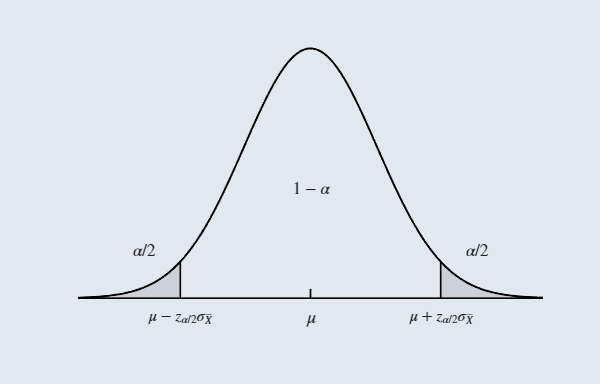

clear
clc

% Parámetros de la distribución normal estándar
mu = 0;
sigma = 1;
x = linspace(-3.5, 3.5, 500);
y = normpdf(x, mu, sigma);

% Color de fondo personalizado
color_fondo = [226 232 240] / 255;

% Configuración de figura y dimensiones
fig = figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5 3.2]);

hold on;

% Valor crítico z_(alpha/2)
z_crit = 1.96;
y_crit = normpdf(z_crit, mu, sigma);

% Sombreado de colas (regiones alpha/2)
x_izq = linspace(-3.5, -z_crit, 100);
y_izq = normpdf(x_izq, mu, sigma);
fill([x_izq, -z_crit, -3.5], [y_izq, 0, 0], [0.8 0.82 0.85], 'EdgeColor', 'none');

x_der = linspace(z_crit, 3.5, 100);
y_der = normpdf(x_der, mu, sigma);
fill([z_crit, x_der, 3.5], [0, y_der, 0], [0.8 0.82 0.85], 'EdgeColor', 'none');

% Curva principal y eje horizontal
plot(x, y, 'k-', 'LineWidth', 1.2);
line([-3.5, 3.5], [0, 0], 'Color', 'k', 'LineWidth', 1);

% Líneas verticales delimitadoras hasta la curva
plot([-z_crit, -z_crit], [0, y_crit], 'k-', 'LineWidth', 1);
plot([z_crit, z_crit], [0, y_crit], 'k-', 'LineWidth', 1);

% Marca central para mu
plot([0, 0], [0, 0.015], 'k-', 'LineWidth', 1);

% Etiquetas matemáticas inferiores
text(0, -0.03, '$\mu$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 11);
text(-z_crit, -0.03, '$\mu - z_{\alpha/2}\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9.5);
text(z_crit, -0.03, '$\mu + z_{\alpha/2}\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9.5);

% Etiquetas de las áreas de las colas (alpha/2)
text(-2.5, 0.075, '$\alpha/2$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 10);
text(2.5, 0.075, '$\alpha/2$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 10);

% Flecha e intervalo central (1 - alpha)
y_arrow = 0.058;
%annotation('doublearrow', [0.32, 0.708], [0.43, 0.43], 'LineWidth', 0.9);
text(0, 3.0*y_arrow, '$1 - \alpha$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'BackgroundColor', color_fondo, 'FontSize', 10);

% Formato de ejes
ylim([-0.07, 0.43]);
xlim([-3.5, 3.5]);
axis off;
hold off;

% Exportación idéntica a tu formato
set(gcf, 'Units', 'inches', 'Position', [0 0 5 3.2]);
exportgraphics(gcf, 'distribucion_alpha_general.png', 'Resolution', 300);
exportgraphics(gcf, 'distribucion_alpha_general.svg', 'ContentType', 'vector');